
$$\dot{x}_1 = x_2\\
\dot{x}_2 = \frac{1}{A}(Bx_2 + Cx_2|x_2| + Dx_1 + E\text{sin}(x_1)) = bx_2 + cx_2|x_2| + dx_1 + e\text{sin}(x_1) $$



syms x1 x2 b c d e real

par_b = -0.1232;
par_c = -0.1015;
par_d = -0.0648;
par_e = -0.8727;
par_f = -0.0044;

f1 = x2;
f2 = b*x2 + c*x2*abs(x2) + d*x1+ e*sin(x1);

eq. points:


$$x_2 = 0\\
x_1 \text{ s.t. } dx_1=-e\sin(x1) $$


The solution (0,0) of this equation is trivial. The existence of other solutions depends on the parameters e and d. To find whether other solutions exist for the given parameters, it is possible to find the intersections numerically by finding the intersections between the curves $y = dx $ and $y = -e\sin(x)$. From this consideration, we start to understand that the most interesting parameters to study in the bifurcation analysis are indeed d and e. In the following paragraphs, an initial analytical study will be carried out. This study will be completed and verified later using Matcont continuation software.

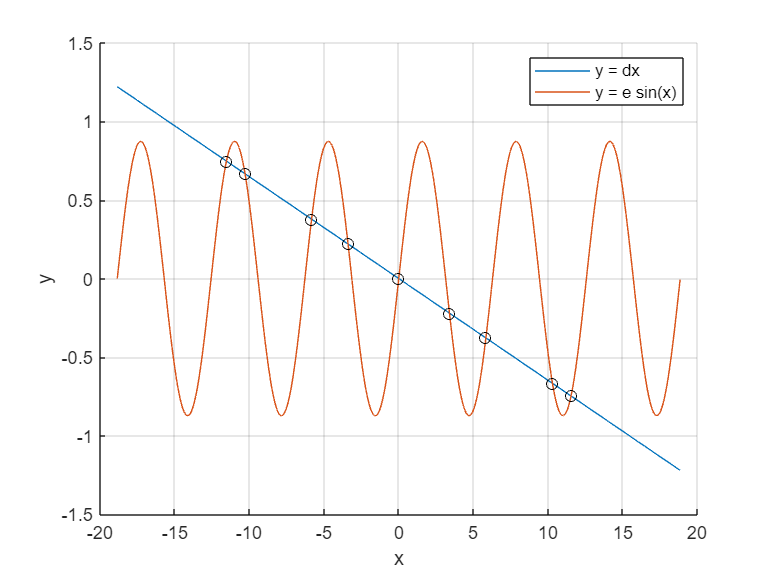

options = optimset('Display', 'off', 'TolFun', 1e-10);
options.TolX = 1e-15;
temp_sol = fsolve(@(x)(par_d*x + par_e*sin(x)),[-4*pi, -3*pi, -2*pi, -pi, 0, pi, 2*pi, 3*pi, 4*pi],options);
x = -6*pi:0.01:6*pi;
figure, hold on
plot(x,par_d*x);
plot(x,-par_e*sin(x));
plot(temp_sol, par_d.*temp_sol, 'o' ,'Color',[0 0 0])
hold off
xlabel('x')
ylabel('y')
legend('y = dx', 'y = e sin(x)')
grid

temp_sol

temp_sol =   -11.5376  -10.2949   -5.8351   -3.3965         0    3.3965    5.8351   10.2949   11.5376


clear temp_sol;

It's immediate to see that by making the modulus of d larger, the steepness of the line increases making some of the equilibria collide and disappear, giving rasie to Saddle Node bifurcations. This type of bifurcation is also called "blue sky" bifurcation since if it's seen the other way around, decreasing the steepness of the line, it will make the equilibrium points appear out of the blue sky.

The same, but in a specular fashion, will happen as d becomes positive and increases.

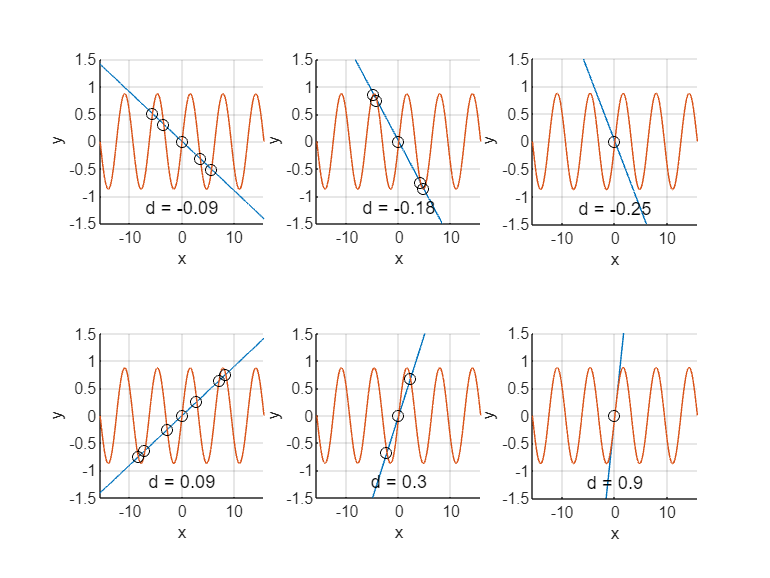

figure

par_d_bif = [-0.09, -0.18, -0.25, 0.09, 0.3, 0.9];
eq_guess = {[-2*pi, -pi, 0, pi, 2*pi];
            [-2*pi, -pi, 0, pi, 2*pi];
            0;
            [-3*pi, -2*pi, -pi, 0, pi, 2*pi, 3*pi];
            [-pi, 0, pi];
            0};
for i=1:length(par_d_bif)
    subplot(2,3,i), hold on
    temp_sol = fsolve(@(x)(par_d_bif(i)*x + par_e*sin(x)),eq_guess{i},options);
    plot(x,par_d_bif(i)*x);
    plot(x,-par_e*sin(x));
    plot(temp_sol, par_d_bif(i)*temp_sol,'o' ,'Color',[0 0 0])
    xlim([-5*pi,5*pi])
    ylim([-1.5,1.5])
    axis square
    clear temp_sol
    text(0,-1.2,{'d = '+ string(par_d_bif(i))},'HorizontalAlignment','center');
    grid
    xlabel('x')
    ylabel('y')
end

J = jacobian([f1;f2], [x1;x2])

$$J = \left(\begin{array}{cc} 0 & 1\\ d+e\,\cos\left(x_{1}\right) & b+c\,\left|x_{2}\right|+c\,x_{2}\,\mathrm{sign}\left(x_{2}\right) \end{array}\right)$$

J00 = subs(J,[x1;x2],[0;0]), traceJ00 = trace(J00), detJ00 = det(J00), disp( string(traceJ00^2-4*detJ00)+ " stable spiral/node depending on the parameters b, d, e")

$$J00 = \left(\begin{array}{cc} 0 & 1\\ d+e & b \end{array}\right)$$

$$traceJ00 = b$$

$$detJ00 = -d-e$$

4*d + 4*e + b^2 stable spiral/node depending on the parameters b, d, e


traceJ00 = vpa(subs(traceJ00,[b,c,d,e],[par_b,par_c,par_d,par_e]),2),...
    detJ00 = vpa(subs(detJ00,[b,c,d,e],[par_b,par_c,par_d,par_e]),2),...
    traceJ00^2-4*detJ00; disp('Stable spiral')

$$traceJ00 = -0.12$$

$$detJ00 = 0.94$$

Stable spiral



Jpi0 = vpa(subs(J,[x1;x2],[3.3965;0]),2), traceJpi0 = trace(Jpi0), detJpi0 = det(Jpi0), disp( string(traceJpi0^2-4*detJpi0));

$$Jpi0 = \left(\begin{array}{cc} 0 & 1.0\\ d-0.97\,e & b \end{array}\right)$$

$$traceJpi0 = b$$

$$detJpi0 = 0.96768666303250938653945922851562\,e-1.0\,d$$

4.0*d - 3.8707466521300375461578369140625*e + b^2
